# **Two-Sample T-Test Example**

Babak Aliyari

Babak.aliyari.edu@gmail.com

#### **Hypothesis Definitions: **

#### **H0 (Null Hypothesis): μ1 = μ2 (The means of the two groups are equal)**

#### **H1 (Alternative Hypothesis): μ1 ≠ μ2 (The means of the two groups are not equal)**

clear all;
close all;
clc;
cd('D:\0 Signal\AmarT');
% Generate data for two independent groups
rng(42); % Set seed for reproducibility
n1 = 40; % Sample size group 1
n2 = 45; % Sample size group 2

% Group 1 data
mean1 = 100;
std1 = 15;
group1 = std1 * randn(n1, 1) + mean1;

% Group 2 data
mean2 = 108; % Different mean for group 2
std2 = 16; % Similar std for group 2
group2 = std2 * randn(n2, 1) + mean2;

% Perform two-sample T-test assuming equal variances
[h, p, ci, stats] = ttest2(group1, group2);

% Display results
fprintf('\nTwo-Sample T-Test (Equal Variances Assumed) Results:\n');


Two-Sample T-Test (Equal Variances Assumed) Results:


fprintf('Group 1 mean: %.2f, Group 2 mean: %.2f\n', mean(group1), mean(group2));

Group 1 mean: 99.86, Group 2 mean: 107.70


fprintf('t-statistic: %.4f\n', stats.tstat);

t-statistic: -2.2445


fprintf('Degrees of freedom: %d\n', stats.df);

Degrees of freedom: 83


fprintf('p-value: %.6f\n', p);

p-value: 0.027459


fprintf('95%% Confidence Interval for difference: [%.2f, %.2f]\n', ci(1), ci(2));

95% Confidence Interval for difference: [-14.78, -0.89]



% Perform two-sample T-test without assuming equal variances
[h_welch, p_welch, ci_welch, stats_welch] = ttest2(group1, group2, 'Vartype', 'unequal');

fprintf('\nWelch''s T-Test (Unequal Variances) Results:\n');


Welch's T-Test (Unequal Variances) Results:


fprintf('t-statistic: %.4f\n', stats_welch.tstat);

t-statistic: -2.2665


fprintf('Degrees of freedom: %.2f\n', stats_welch.df);

Degrees of freedom: 82.83


fprintf('p-value: %.6f\n', p_welch);

p-value: 0.026029


fprintf('95%% Confidence Interval for difference: [%.2f, %.2f]\n', ci_welch(1), ci_welch(2));

95% Confidence Interval for difference: [-14.71, -0.96]



% Interpret results
if h == 1
    fprintf('\nConclusion with equal variance assumption: Reject H0 - Significant difference between groups\n');
else
    fprintf('\nConclusion with equal variance assumption: Fail to reject H0 - No significant difference between groups\n');
end


Conclusion with equal variance assumption: Reject H0 - Significant difference between groups



if h_welch == 1
    fprintf('Conclusion with Welch''s test: Reject H0 - Significant difference between groups\n');
else
    fprintf('Conclusion with Welch''s test: Fail to reject H0 - No significant difference between groups\n');
end

Conclusion with Welch's test: Reject H0 - Significant difference between groups


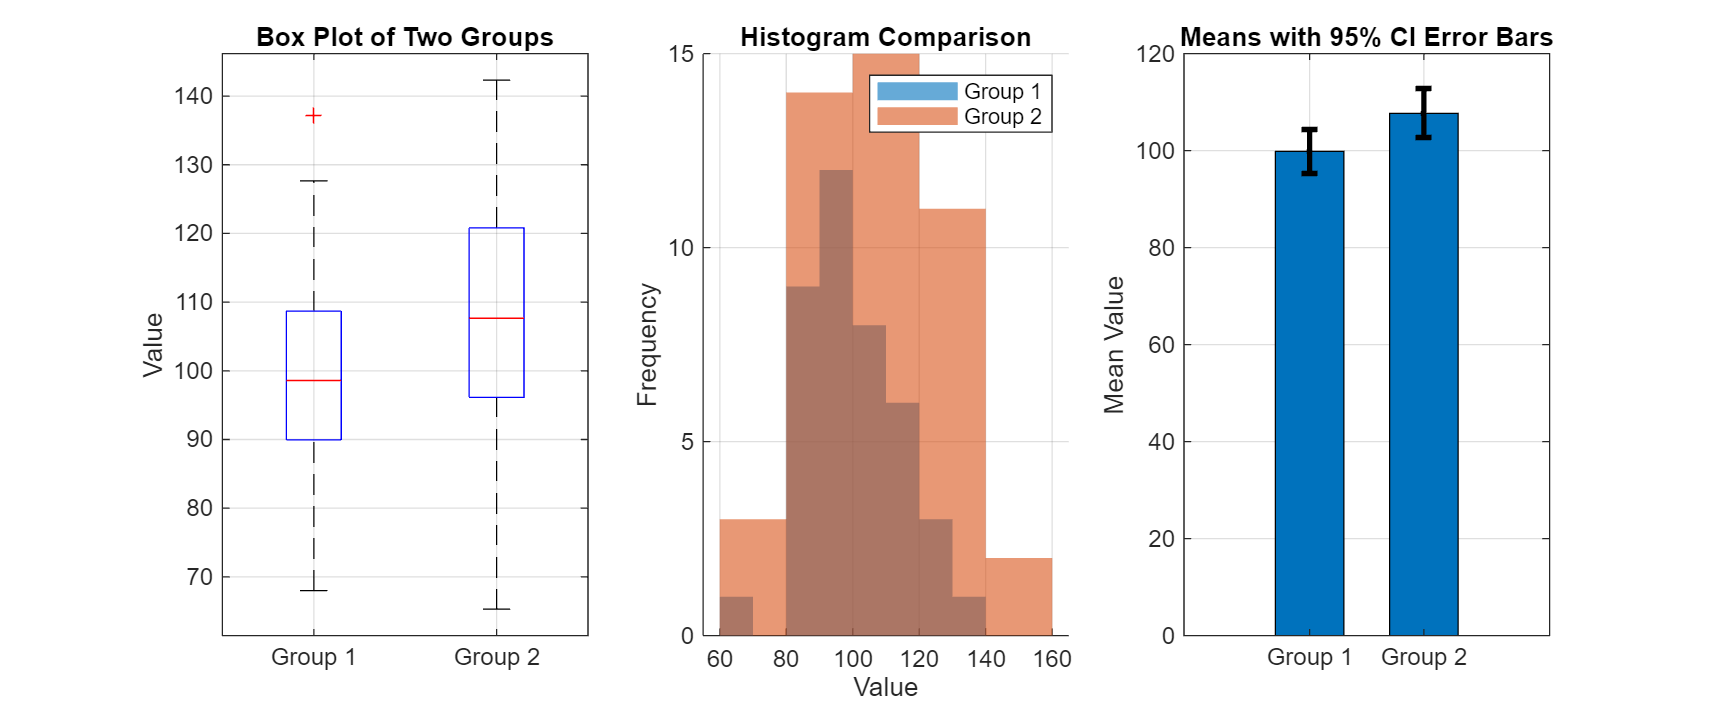


%% Visualization
% Figure 1: Box Plot
figure('Position', [100, 100, 1200, 500]);
subplot(1,3,1);
boxplot([group1; group2], [ones(n1, 1); 2*ones(n2, 1)]);
set(gca, 'XTickLabel', {'Group 1', 'Group 2'});
ylabel('Value');
title('Box Plot of Two Groups');
grid on;

% Figure 2: Histograms
subplot(1,3,2);
hold on;
histogram(group1, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
histogram(group2, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
xlabel('Value');
ylabel('Frequency');
title('Histogram Comparison');
legend('Group 1', 'Group 2');
grid on;
hold off;

% Figure 3: Mean Comparison with Error Bars
subplot(1,3,3);
means = [mean(group1), mean(group2)];
stderrs = [std(group1)/sqrt(n1), std(group2)/sqrt(n2)];
bar(means, 'FaceColor', 'flat', 'BarWidth', 0.6);
hold on;
errorbar(1:2, means, stderrs*1.96, 'k.', 'LineWidth', 2);
set(gca, 'XTickLabel', {'Group 1', 'Group 2'});
ylabel('Mean Value');
title('Means with 95% CI Error Bars');
grid on;

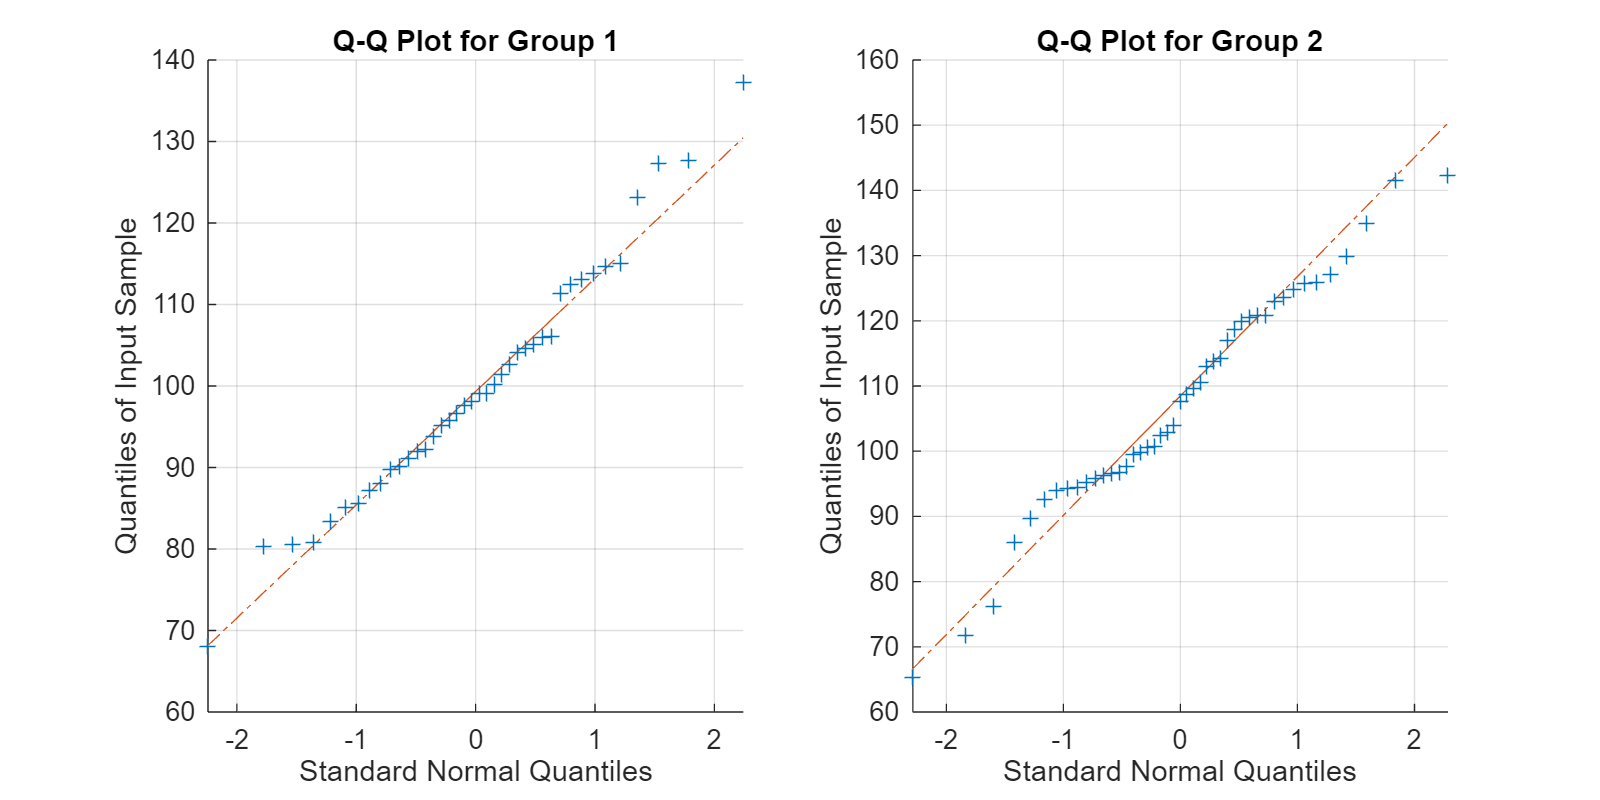


% Figure 4: Q-Q Plots for Normality Check
figure('Position', [100, 100, 800, 400]);
subplot(1,2,1);
qqplot(group1);
title('Q-Q Plot for Group 1');
grid on;

subplot(1,2,2);
qqplot(group2);
title('Q-Q Plot for Group 2');
grid on;

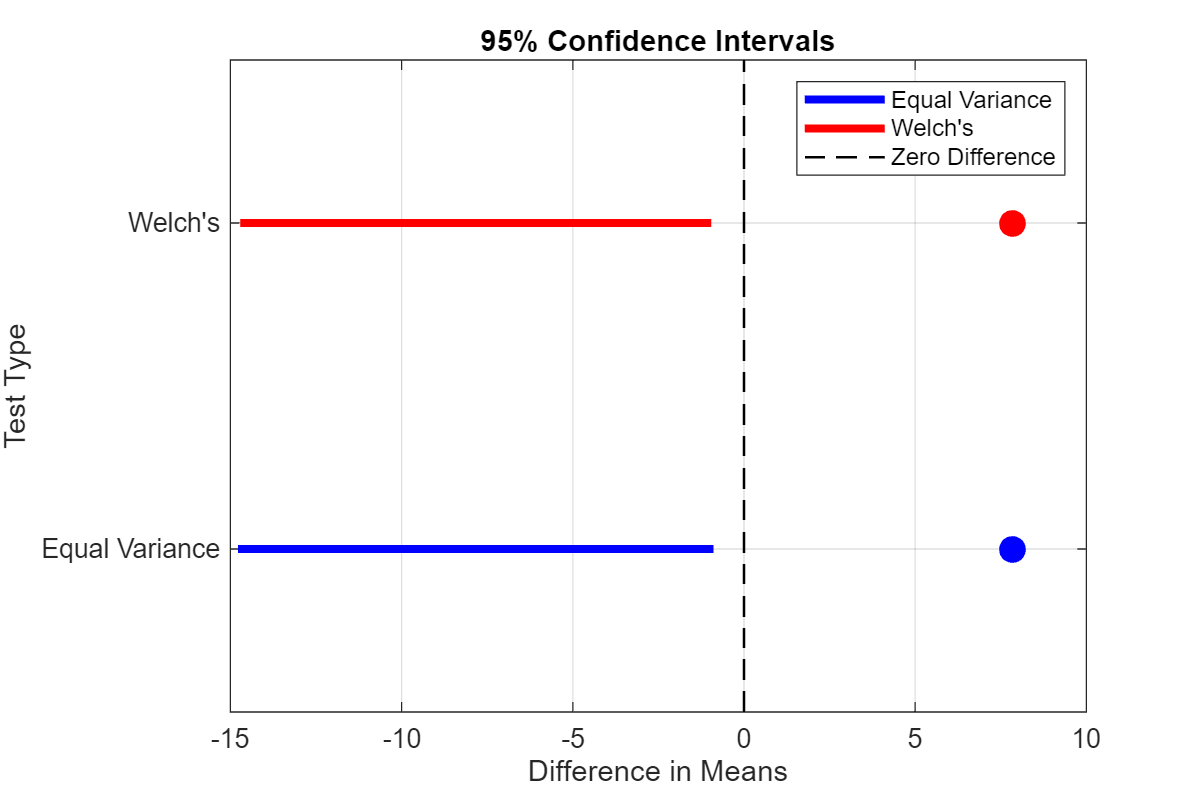


% Figure 5: Confidence Interval Visualization
figure('Position', [100, 100, 600, 400]);
differences = mean(group2) - mean(group1);
plot([ci(1) ci(2)], [1 1], 'LineWidth', 3, 'Color', 'b');
hold on;
plot([ci_welch(1) ci_welch(2)], [2 2], 'LineWidth', 3, 'Color', 'r');
plot([0 0], [0.5 2.5], 'k--', 'LineWidth', 1);
scatter(differences, 1, 100, 'bo', 'filled');
scatter(differences, 2, 100, 'ro', 'filled');
xlabel('Difference in Means');
ylabel('Test Type');
title('95% Confidence Intervals');
legend('Equal Variance', 'Welch''s', 'Zero Difference');
set(gca, 'YTick', [1 2], 'YTickLabel', {'Equal Variance', 'Welch''s'});
grid on;